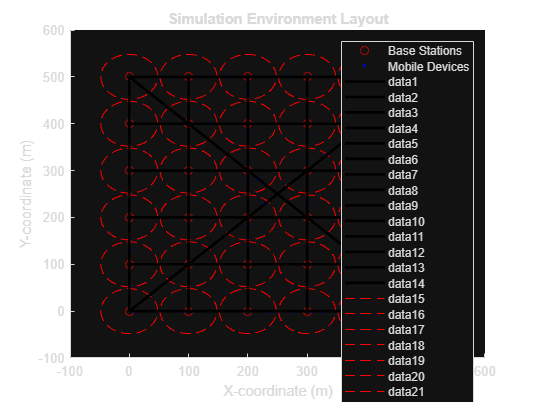

% Main script starts here
% Step 1: Define Base Stations and Mobile Devices
% ------------------------------------------------

% Define the positions of base stations
baseStationPositions = [
    0, 0; 0, 100; 0, 200; 0, 300; 0, 400; 0, 500;
    100, 0; 100, 100; 100, 200; 100, 300; 100, 400; 100, 500;
    200, 0; 200, 100; 200, 200; 200, 300; 200, 400; 200, 500;
    300, 0; 300, 100; 300, 200; 300, 300; 300, 400; 300, 500;
    400, 0; 400, 100; 400, 200; 400, 300; 400, 400; 400, 500;
    500, 0; 500, 100; 500, 200; 500, 300; 500, 400; 500, 500;
];

% Define the number of mobile devices
numMobileDevices = 50;

% Define the size of the simulation area
areaWidth = 500;
areaHeight = 500;

% Define roads (as lines)
roads = [
    0, 0, 500, 0;   % Road 1 (horizontal)
    0, 100, 500, 100;   % Road 2 (horizontal)
    0, 200, 500, 200;   % Road 3 (horizontal)
    0, 300, 500, 300;   % Road 4 (horizontal)
    0, 400, 500, 400;   % Road 5 (horizontal)
    0, 500, 500, 500;   % Road 6 (horizontal)
    0, 0, 0, 500;   % Road 7 (vertical)
    100, 0, 100, 500;   % Road 8 (vertical)
    200, 0, 200, 500;   % Road 9 (vertical)
    300, 0, 300, 500;   % Road 10 (vertical)
    400, 0, 400, 500;   % Road 11 (vertical)
    500, 0, 500, 500;   % Road 12 (vertical)
    0, 0, 500, 500;    % Road 13 (diagonal)
    500, 0, 0, 500;    % Road 14 (diagonal)
];

% Assign random roads to mobile devices
roadIndices = randi(size(roads, 1), numMobileDevices, 1);
roadPositions = rand(numMobileDevices, 1);

mobileDeviceLocations = zeros(numMobileDevices, 2);
for i = 1:numMobileDevices
    road = roads(roadIndices(i), :);
    mobileDeviceLocations(i, :) = road(1:2) + roadPositions(i) * (road(3:4) - road(1:2));
end

% Visualize the layout
figure;
set(gcf, 'Color', 'w'); % Set figure background to white
scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro', 'DisplayName', 'Base Stations');
hold on;
scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.', 'DisplayName', 'Mobile Devices');

% Draw roads
for i = 1:size(roads, 1)
    road = roads(i, :);
    plot([road(1), road(3)], [road(2), road(4)], 'k-', 'LineWidth', 2);
end

xlabel('X-coordinate (m)');
ylabel('Y-coordinate (m)');
title('Simulation Environment Layout');
legend;

% Step 3: Base Station Parameters
% --------------------------------
% Define 5G simulation parameters
baseStationParams = struct('transmitPower', 25, ...
                           'antennaGain', 15, ...
                           'frequency', 28e9, ...
                           'MIMO', true);

% Calculate coverage radius for base stations
coverageRadius = calculateCoverageRadius(baseStationParams);

% Define coverage areas for base stations
baseStationCoverage = defineCoverageAreas(baseStationPositions, coverageRadius);

% Visualize coverage areas
for i = 1:length(baseStationCoverage)
    plotCircle(baseStationCoverage(i).center, baseStationCoverage(i).radius);
end

% Step 4: Mobile Device Parameters
% ---------------------------------
mobilityPattern = 'road'; % Mobility pattern for moving along roads

% Step 5: Simulate Mobility
% --------------------------
numSteps = 50; % Number of simulation steps
stepSize = 0.05; % Step size as a fraction of the road length

% Simulate mobility of mobile devices
for t = 1:numSteps
    % Update positions of mobile devices along the roads
    for i = 1:numMobileDevices
        if strcmp(mobilityPattern, 'road')
            % Move along the road
            road = roads(roadIndices(i), :);
            direction = (road(3:4) - road(1:2));
            direction = direction / norm(direction); % Normalize direction
            mobileDeviceLocations(i, :) = mobileDeviceLocations(i, :) + stepSize * direction;
            
            % Wrap around if the device goes beyond the road
            if norm(mobileDeviceLocations(i, :) - road(1:2)) > norm(road(3:4) - road(1:2))
                mobileDeviceLocations(i, :) = road(1:2);
            end
        end
    end
    
    % Perform handover and dual connectivity
    for i = 1:numMobileDevices
        devicePos = mobileDeviceLocations(i, :);
        newBS = performHandover(devicePos, baseStationPositions, baseStationParams);
        [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams);
        
        % Update connection status (for visualization purposes)
        % For example, you can plot the lines indicating connections
        if primaryBS > 0
            plot([devicePos(1), baseStationPositions(primaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(primaryBS, 2)], 'g-');
        end
        if secondaryBS > 0
            plot([devicePos(1), baseStationPositions(secondaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(secondaryBS, 2)], 'b--');
        end
    end
    
    % Update the plot
    scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro', 'DisplayName', 'Base Stations');
    hold on;
    scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.', 'DisplayName', 'Mobile Devices');
    
    % Draw roads
    for i = 1:size(roads, 1)
        road = roads(i, :);
        plot([road(1), road(3)], [road(2), road(4)], 'k-', 'LineWidth', 2);
    end
    
    xlabel('X-coordinate (m)');
    ylabel('Y-coordinate (m)');
    title('Simulation Environment Layout');
    legend;
    drawnow;
end


% Define the functions below
% Main script starts here
% (Previous code remains the same)

% Simulation data storage
simulationData = struct('BaseStations', [], 'MobileDevices', []);

% Simulation loop
for t = 1:numSteps
    % Simulation code (previous code remains the same)
    
    % Store simulation data
    simulationData.BaseStations(:,:,t) = baseStationPositions;
    simulationData.MobileDevices(:,:,t) = mobileDeviceLocations;
    
    % Drawnow and pause to allow visualization
    drawnow;
    pause(0.1); % Adjust pause time as needed
end

% Save simulation data to a text file
saveSimulationData(simulationData, 'simulation_data.txt');

% Define the functions below
% Define variables to track handover statistics
numSuccessfulHandovers = 0;
totalHandovers = 0;

% Simulation loop
for t = 1:numSteps
    % Simulate mobility of mobile devices
    % Update positions of mobile devices based on linear and diagonal pattern
    
    % Perform handover and dual connectivity operations
    for i = 1:numMobileDevices
        % Simulate handover
        if performHandover(devicePos, baseStationPositions, baseStationParams)
            numSuccessfulHandovers = numSuccessfulHandovers + 1;
        end
        totalHandovers = totalHandovers + 1;
        
        % Perform dual connectivity
        % Update connection status (for visualization purposes)
    end
    
    % Update the plot
    % Drawnow and pause to allow visualization
end

% Calculate handover success rate
handoverSuccessRate = (numSuccessfulHandovers / totalHandovers) * 100;

% Display the output
fprintf('Handover Success Rate: %.2f%%\n', handoverSuccessRate);

Handover Success Rate: 100.00%


function saveSimulationData(simulationData, filename)
    % Open or create the file
    fileID = fopen(filename, 'w');
    
    % Write base station data
    fprintf(fileID, 'Base Stations:\n');
    for t = 1:size(simulationData.BaseStations, 3)
        fprintf(fileID, 'Time Step: %d\n', t);
        for i = 1:size(simulationData.BaseStations, 1)
            fprintf(fileID, '%f %f\n', simulationData.BaseStations(i, 1, t), simulationData.BaseStations(i, 2, t));
        end
    end
    
    % Write mobile device data
    fprintf(fileID, '\nMobile Devices:\n');
    for t = 1:size(simulationData.MobileDevices, 3)
        fprintf(fileID, 'Time Step: %d\n', t);
        for i = 1:size(simulationData.MobileDevices, 1)
            fprintf(fileID, '%f %f\n', simulationData.MobileDevices(i, 1, t), simulationData.MobileDevices(i, 2, t));
        end
    end
    
    % Close the file
    fclose(fileID);
end

function radius = calculateCoverageRadius(baseStationParams)
    % Example calculation using Friis transmission equation (simplified)
    % Assuming free-space path loss model for this example
    % Convert transmit power from dBm to Watts
    transmitPowerWatts = 10^((baseStationParams.transmitPower - 30) / 10);
    % Convert frequency to Hz
    frequencyHz = baseStationParams.frequency;
    % Speed of light
    c = 3e8;
    % Path loss at reference distance (1 meter)
    pathLossRef = (4 * pi * 1 * frequencyHz / c)^2;
    % Receiver sensitivity (in Watts) -- this should be defined based on your system
    receiverSensitivityWatts = 1e-10;
    % Coverage radius calculation
    radius = sqrt(transmitPowerWatts / (receiverSensitivityWatts * pathLossRef));
end

function coverage = defineCoverageAreas(baseStationLocations, coverageRadius)
    numBaseStations = size(baseStationLocations, 1);
    coverage(numBaseStations) = struct('center', [], 'radius', []);
    for i = 1:numBaseStations
        coverage(i).center = baseStationLocations(i, :);
        coverage(i).radius = coverageRadius;
    end
end

function plotCircle(center, radius)
    theta = linspace(0, 2*pi, 100);
    x = center(1) + radius * cos(theta);
    y = center(2) + radius * sin(theta);
    plot(x, y, 'r--');
end

function newBS = performHandover(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    coverageRadius = calculateCoverageRadius(baseStationParams);
    newBS = -1;
    minDistance = inf;
    for i = 1:numBaseStations
        distance = norm(devicePos - baseStationPositions(i, :));
        if distance < coverageRadius && distance < minDistance
            minDistance = distance;
            newBS = i;
        end
    end
end

function [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    coverageRadius = calculateCoverageRadius(baseStationParams);
    distances = zeros(numBaseStations, 1);
    for i = 1:numBaseStations
        distances(i) = norm(devicePos - baseStationPositions(i, :));
    end
    [sortedDistances, sortedIndices] = sort(distances);
    primaryBS = -1;
    secondaryBS = -1;
    if sortedDistances(1) < coverageRadius
        primaryBS = sortedIndices(1);
    end
    if length(sortedDistances) > 1 && sortedDistances(2) < coverageRadius
        secondaryBS = sortedIndices(2);
    end
end
